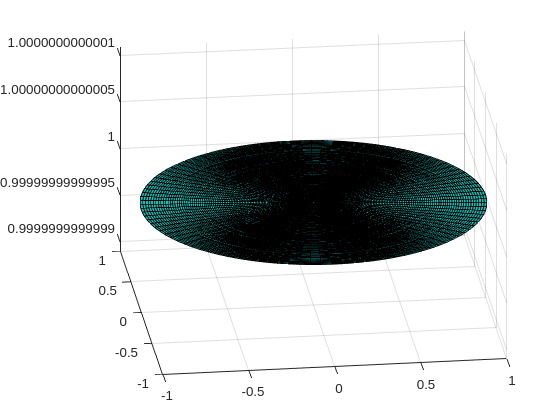

%C={(x,y,z):x^2+y^2<=1 ^ z=1}
%Como o theta é a projeção no plano XOZ, logo varia entre 0 e 2*pi
%Phi varia entre 0e pi/4 -> elevation varia de pi/4 a pi/2

azimuth=linspace(0,2*pi);
elevation=linspace(pi/4,pi/2);

[azimuth, elevation]=meshgrid(azimuth,elevation);
R=1./sin(elevation);

[x,y,z]=sph2cart(azimuth, elevation, R);

surf(x,y,z);